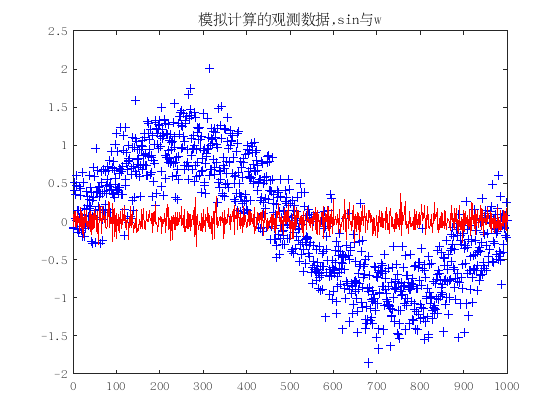

close all;
%load ../bin/log_file4.txt;
load("log.txt");
% This is the data format:
% iteration# [TAB] true1 [TAB] estimate1 [TAB] measured1 [TAB] 
% true2 [TAB] estimate2 [TAB] measured2 [EOL]

% h = figure;
% 
% subplot(2, 1, 1);
% hold;
% plot(log_file4(:,1), log_file4(:,2), '+b');
% plot(log_file4(:,1), log_file4(:,3), 'r');
% plot(log_file4(:,1), log_file4(:,4), 'g');
% xlabel('Time');
% ylabel('Position');
% title('Extended Kalman Filtering of a Sine Wave - Position');
% legend('Position Measurements', 'True Position', 'Position Estimates');
% 
% subplot(2, 1, 2);
% hold;
% plot(log_file4(:,1), log_file4(:,5), '+b');
% plot(log_file4(:,1), log_file4(:,6), 'r');
% plot(log_file4(:,1), log_file4(:,7), 'g');
% xlabel('Time');
% ylabel('Frequency');
% title('Extended Kalman Filtering of a Sine Wave - Frequency');
% legend('Frequency Measurements', 'True Frequency', 'Frequency Estimates');
% 
% saveas(h, 'ex4.png');


plot(log(:,1), log(:,2), '+b');
hold on;
plot(log(:,1), log(:,3), 'r');
title("考虑噪声模拟计算的观测数据,sin与w");

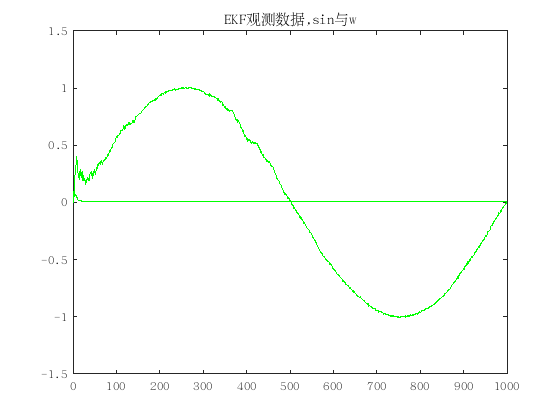

figure
plot(log(:,1), log(:,4), 'g');
hold on;
plot(log(:,1), log(:,5), 'g');
title("EKF观测数据,sin与w");

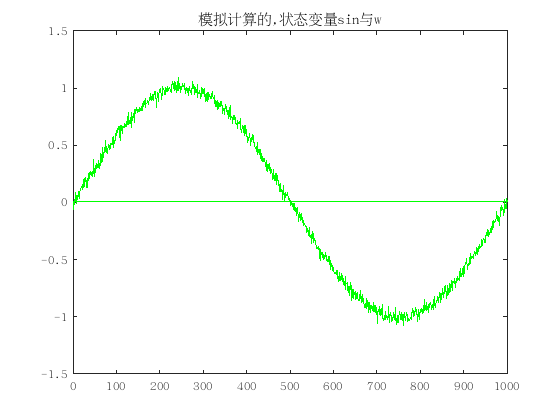

figure
plot(log(:,1), log(:,6), 'g');
hold on;
plot(log(:,1), log(:,7), 'g');
title("模拟计算的,状态变量sin与w");

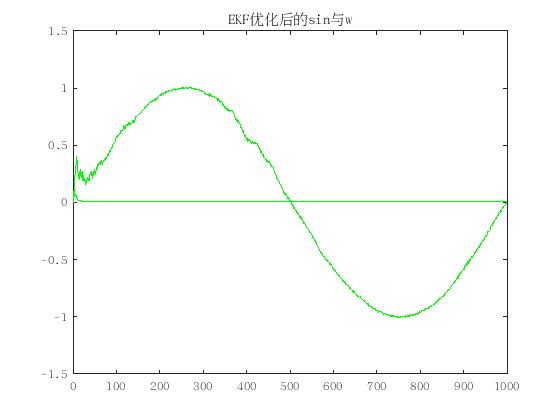

figure
% ylim([-0.02,0.02])
plot(log(:,1), log(:,8), 'g');
hold on;
plot(log(:,1), log(:,9), 'g');
title("EKF优化后的sin与w");